# **Half Course Demo PBE**

### **Chaimae Fathallah i Laura Pérez**

## 1.- THD (Total Harmonic Distortion)

En aquesta secció mostrarem la implementació del càlcul del THD, un paràmetre que relaciona la potència dels armònics secundaris amb la de l'armonic principal.

En primera instancia definim els paràmetres dels senyals amb els que treballarem.

clear all;

Fs           = 48000;            % Freqüència de Mostreig
duration     = 1.0; 

F = 1000;                        % Freqüència en Hz 
Fd = F*duration;                 % Freqüència per la duració
t = 0:(1/Fs):duration-(1/Fs);    % Eix de temps
n = 0:1:duration*Fs-(1/Fs);      % Vector n

A continuació definim el senyal d'entrada i el de sortida

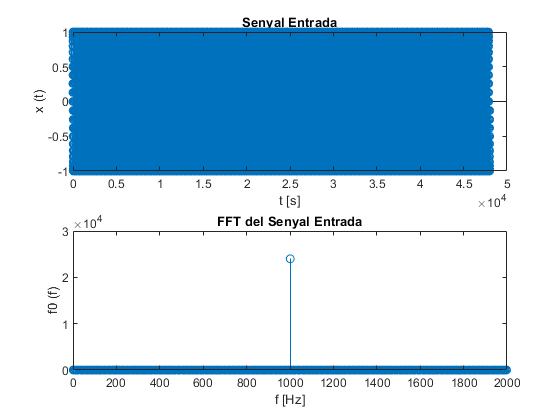

% Senyal d'entrada
x = sin(2*pi*n*(Fd/Fs))';        % Generació del senyal d'entrada
f0 = abs(fft(x));                % Módul de la fft del senyal d'entrada

figure(1)                        % Plot de la fft del senyal d'entrada
subplot(2,1,1); stem(x); title('Senyal Entrada') ;xlabel('t [s]');ylabel('x (t)');
subplot(2,1,2); stem(f0); title('FFT del Senyal Entrada') ;xlabel('f [Hz]');ylabel('f0 (f)');

subplot(2,1,2)
xlim([0 2000])

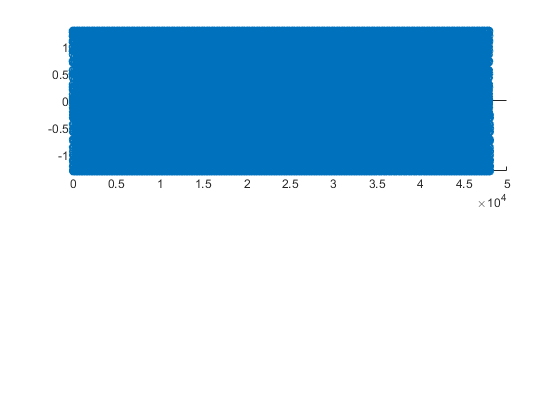

% Senyal de sortida amb harmònics d'amplituds variables

A1 = 0.5;                         % Amplituds dels harmònics del senyal de sortida
A2 = 0;
A3 = 0;
A4 = 0;

y = sin(2*pi*n*(Fd/Fs))' + A1*sin(2*pi*n*(2*Fd/Fs))' + A2*sin(2*pi*n*(3*Fd/Fs))' + A3*sin(2*pi*n*(4*Fd/Fs))' + A4*sin(2*pi*n*(5*Fd/Fs))';

f = abs(fft(y));                 % Módul de la fft del senyal de sortida

figure(2)                        % Plot de la fft del senyal de sortida
subplot(2,1,1); stem(y); title('Senyal Sortida') ;xlabel('t [s]');ylabel('y (t)');

subplot(2,1,2); stem(f); title('FFT del Senyal Sortida') ;xlabel('f [Hz]');ylabel('f (f)');

subplot(2,1,2)
xlim([0 6000])

Finalment busquem la posició del màxim (harmònic principal) i calculem el THD

% Posició del màxim
M = find(f>1,1) - 1;

% Càlcul del THD
thd = (sqrt((f(2*M+1))^2+(f(3*M+1))^2+(f(4*M+1))^2+(f(5*M+1))^2)/sqrt((f(M+1))^2))*100;
X = ['El THD és del ', num2str(thd,4),' %.'];
disp(X);

## 2.- THD + N (Total Harmonic Distortion + Noise)

En aquesta secció mostrarem la implementació del càlcul del THD + N. A diferencia de l'anterior, aquest té en compte el soroll que es pot ocasionar.

Com en l'apartat anterior, definirem els paràmetres dels senyals amb els que treballarem.

clear all;

Fs           = 48000;            % Freqüència de Mostreig
duration     = 1.0; 

F = 1000;                        % Freqüència en Hz 
Fd = F*duration;                 % Freqüència per la duració
t = 0:(1/Fs):duration-(1/Fs);    % Eix de temps
n = 0:1:duration*Fs-(1/Fs);      % Vector n

A continuació definim el senyal d'entrada, el soroll i el senyal de sortida

% Senyal d'entrada
x = sin(2*pi*n*(Fd/Fs))';        % Generació del senyal d'entrada
f0 = abs(fft(x));                % Módul de la fft del senyal d'entrada

figure(1)                        % Plot de la fft del senyal d'entrada
subplot(2,1,1); stem(x); title('Senyal Entrada') ;xlabel('t [s]');ylabel('x (t)');
subplot(2,1,2); stem(f0); title('FFT del Senyal Entrada') ;xlabel('f [Hz]');ylabel('f0 (f)');

subplot(2,1,2)
xlim([0 2000])

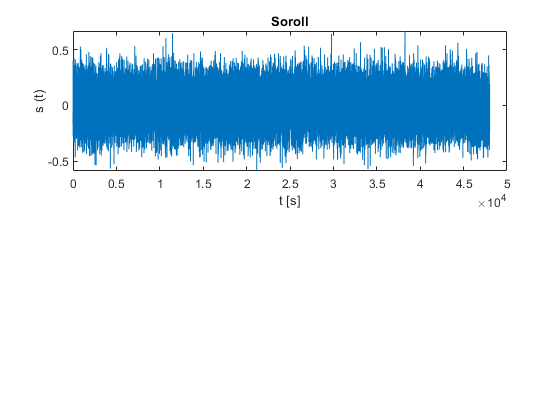

% Soroll
s = 0.15*randn(1, Fs);            % Generació del soroll

figure(2)
plot(s); title('Soroll') ;xlabel('t [s]');ylabel('s (t)');

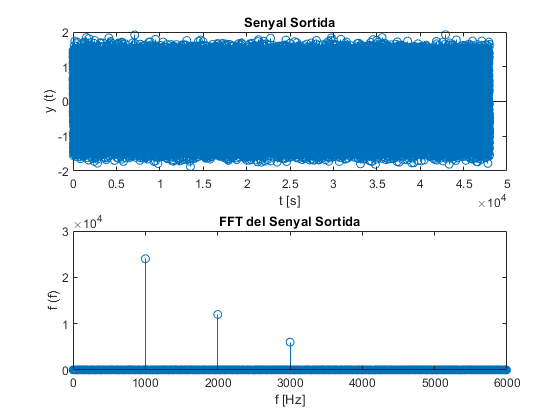

% Senyal de sortida amb armonics d'amplituds variables

A1 = 0.5;                         % Amplituds dels harmònics del senyal de sortida
A2 = 0.25;
A3 = 0;
A4 = 0;

y = sin(2*pi*n*(Fd/Fs))' + A1*sin(2*pi*n*(2*Fd/Fs))' + A2*sin(2*pi*n*(3*Fd/Fs))' + A3*sin(2*pi*n*(4*Fd/Fs))' + A4*sin(2*pi*n*(5*Fd/Fs))' + s'; 

f = abs(fft(y));                 % Módul de la fft del senyal de sortida

figure(3)                        % Plot de la fft del senyal de sortida
subplot(2,1,1); stem(y); title('Senyal Sortida') ;xlabel('t [s]');ylabel('y (t)');
subplot(2,1,2); stem(f); title('FFT del Senyal Sortida') ;xlabel('f [Hz]');ylabel('f (f)');

subplot(2,1,2)
xlim([0 6000])

A continuació calculem, per separat, la potència de l'harmònic principal i la potència de la resta d'harmònic més la del soroll. Per fer-ho obtenim la posició del màxim com hem fet en el cas anterior.

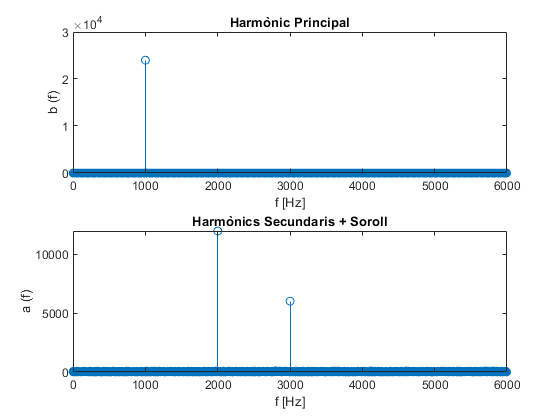

% Posició del màxim
M = find(f>1000,1) - 1;

% Separació de l'harmònic principal de la resta de la funció
fArm1 = f;
fSenseArm1 = f;

for i = 1:1:(M-5)
    fArm1(i) = 0;
end
for i = (M-5):1:(M+5)
    fSenseArm1(i) = 0;
end
for i = (M+5):1:(Fs-M-5)
    fArm1(i) = 0;
end
for i = (Fs-M-5):1:(Fs-M+5)
    fSenseArm1(i) = 0;
end
for i = (Fs-M+5):1:Fs-1
    fArm1(i) = 0;
end

a = ifft(fSenseArm1);
b = ifft(fArm1);

P = sum((abs(a)).^2)/Fs;
Pa = sum((abs(b)).^2)/Fs;

figure(4)                        % Plot de la fft del senyal de sortida
subplot(2,1,1); stem(abs(fft(b))); title('Harmònic Principal') ;xlabel('f [Hz]');ylabel('b (f)');
subplot(2,1,2); stem(abs(fft(a))); title('Harmònics Secundaris + Soroll') ;xlabel('f [Hz]');ylabel('a (f)');
subplot(2,1,1)
xlim([0 6000])
subplot(2,1,2)
xlim([0, 6000])

Finalment calculem el THD + N

% THD + N

thdn = (P/Pa)*100;
X = ['El THD + N és del ', num2str(thdn,4),' %.'];
disp(X);

El THD + N és del 35.66 %.


## 3.- DF (Distortion Factor)

El Factor de Distorsió ens permet coneixer el grau de distorsió del nostre amplificador. Per fer-ho relaciona la potència de l'harmònic principal amb la potència total del senyal.

Com als apartats anteriors definirem els paràmetres amb els que farem els càlculs.

clear all;

Fs           = 48000;            % Freqüència de Mostreig
duration     = 1.0; 

F = 1000;                        % Freqüència en Hz 
Fd = F*duration;                 % Freqüència per la duració
t = 0:(1/Fs):duration-(1/Fs);    % Eix de temps
n = 0:1:duration*Fs-(1/Fs);      % Vector n

A continuació definim el senyal d'entrada i el de sortida

% Senyal d'entrada
x = sin(2*pi*n*(Fd/Fs))';        % Generació del senyal d'entrada
f0 = abs(fft(x));                % Módul de la fft del senyal d'entrada

figure(1)                        % Plot de la fft del senyal d'entrada
subplot(2,1,1); stem(x); title('Senyal Entrada') ;xlabel('t [s]');ylabel('x (t)');
subplot(2,1,2); stem(f0); title('FFT del Senyal Entrada') ;xlabel('f [Hz]');ylabel('f0 (f)');

subplot(2,1,2)
xlim([0 2000])
% Senyal de sortida amb armonics d'amplituds variables

A1 = 0.7;                         % Amplituds dels harmònics del senyal de sortida
A2 = 0.5;
A3 = 0.2;
A4 = 0.1;

y = sin(2*pi*n*(Fd/Fs))' + A1*sin(2*pi*n*(2*Fd/Fs))' + A2*sin(2*pi*n*(3*Fd/Fs))' + A3*sin(2*pi*n*(4*Fd/Fs))' + A4*sin(2*pi*n*(5*Fd/Fs))';

f = abs(fft(y));                 % Módul de la fft del senyal de sortida

figure(2)                        % Plot de la fft del senyal de sortida
subplot(2,1,1); stem(y); title('Senyal Sortida') ;xlabel('t [s]');ylabel('y (t)');
subplot(2,1,2); stem(f); title('FFT del Senyal Sortida') ;xlabel('f [Hz]');ylabel('f (f)');

subplot(2,1,2)
xlim([0 6000])

Finalment busquem la posició del màxim (harmònic principal) i calculem el THD

% Càlcul del màxim
a = max(f,[],'all');

for i = 1:1:Fs
   if f(i) == a
       M = i - 1;
       break
   end
end

% Càlcul del DF
df = (sqrt((f(M+1))^2)/sqrt(((f(M+1))^2+(f(2*M+1))^2+(f(3*M+1))^2+(f(4*M+1))^2+(f(5*M+1))^2)))*100;
X = ['El DF és del ', num2str(df,4),' %.'];
disp(X);

## 4.- IMD (Intermodulation Distortion)

En aquest apartat, calcularem la distorsió provocada per la intermodulació produida quan tenim dos harmònics principals.

Començarem definint els paràmetres amb els que treballarem. En aquest cas tindrem dues sinusoides a l'entrada amb les seves corresponents freqüències.

clear all;

Fs           = 48000;            % Freqüència de Mostreig
duration     = 1.0; 

F1 = 1000;                       % Freqüència 1 
F2 = 1100;                       % Freqüènica 2
Fd1 = F1*duration;               % Freqüència 1 per la duració
Fd2 = F2*duration;               % Freqüència 2 per la duració
t = 0:(1/Fs):duration-(1/Fs);    % Eix de temps
n = 0:1:duration*Fs-(1/Fs);      % Vector n

A continuació definim els senyals d'entrada i el de sortida (definint cadascun dels harmònics).

% Senyals d'entrada
x1 = sin(2*pi*n*(F1/Fs))';       % Generació del sinus 1
x2 = sin(2*pi*n*(F2/Fs))';       % Generació del sinus 2
f01 = abs(fft(x1));              % Módul de la fft del sinus 1
f02 = abs(fft(x2));              % Módul de la fft del sinus 2
x = x1 + x2;                     % Generació del senyal d'entrada
f0 = abs(fft(x));                % Módul de la fft del senyal d'entrada

figure(1)                        % Plot de la fft del senyal d'entrada
subplot(2,3,1); stem(x1); title('Senyal Entrada 1') ;xlabel('t [s]');ylabel('x (t)');
subplot(2,3,2); stem(x2); title('Senyal Entrada 2') ;xlabel('t [s]');ylabel('x (t)');
subplot(2,3,3); stem(x); title('Senyal Entrada total') ;xlabel('t [s]');ylabel('x (t)');
subplot(2,3,4); stem(f01); title('FFT del Senyal Entrada 1') ;xlabel('f [Hz]');ylabel('f0 (f)');
subplot(2,3,5); stem(f02); title('FFT del Senyal Entrada 2') ;xlabel('f [Hz]');ylabel('f0 (f)');
subplot(2,3,6); stem(f0); title('FFT del Senyal Entrada total') ;xlabel('f [Hz]');ylabel('f0 (f)');
subplot(2,3,4)
xlim([0 2000])
subplot(2,3,5)
xlim([0 2000])
subplot(2,3,6)
xlim([0 2000])
% Harmònics del senyal de sortida

% Segon ordre:
a21 = sin(2*pi*n*((F1+F2)/Fs))';
a22 = sin(2*pi*n*(2*F1/Fs))';
a23 = sin(2*pi*n*(2*F2/Fs))';

% Tercer ordre:
a31 = sin(2*pi*n*((2*F1-F2)/Fs))';
a32 = sin(2*pi*n*((2*F2-F1)/Fs))';
a33 = sin(2*pi*n*((3*F1)/Fs))';
a34 = sin(2*pi*n*((2*F1+F2)/Fs))';
a35 = sin(2*pi*n*((2*F2+F1)/Fs))';
a36 = sin(2*pi*n*((3*F2)/Fs))';

% Senyal de sortida amb armonics d'amplituds variables

A1 = 0.5;
A2 = 0.35;
A3 = 0.25;
A4 = 0.3;
A5 = 0.2;

y = x1 + x2 + A2*a21 + A3*a22 + A3*a23 + A1*a31 + A1*a32 + A5*a33 + A4*a34 + A4*a35 + A5*a36;

f = abs(fft(y));                 % Módul de la fft del senyal de sortida

figure(2)                        % Plot de la fft del senyal de sortida
subplot(2,1,1); stem(y); title('Senyal Sortida') ;xlabel('t [s]');ylabel('y (t)');
subplot(2,1,2); stem(f); title('FFT del Senyal Sortida') ;xlabel('f [Hz]');ylabel('f (f)');

subplot(2,1,2)
xlim([0 6000])

Finalment calculem la posició dels dos màxims i fem el càlcul del IMD

% Generació de paràmetres necessaris pel càlcul
s = f;                           % Còpia del valor absolut de la fft del senyal de sortida
M = find(s>1,5) - 1;             % Vector dels primers màxims relatius

M1 = 1;
M2 = 1;

% Càlcul del primer màxim
for i = 1:1:5
    if s(M(i)+1) > s(M1)
        M1 = M(i) + 1;
    end
end
s(M1) = 0;                        % Valor del primer màxim a zero per no generar problemes en la cerca del segon

% Càlcul del segon màxim
for i = 1:1:5
    if s(M(i) + 1) > s(M2)
        M2 = M(i) + 1;
    end
end

M1 = M1 - 1;
M2 = M2 - 1;

% Càlcul del IMD
imd = (sqrt((f(M1+M2+1))^2+(f(2*M1+1))^2+(f(2*M2+1))^2+(f(2*M1-M2+1))^2+(f(2*M2-M1+1))^2+(f(3*M1+1))^2+(f(3*M2+1))^2+(f(2*M1+M2+1))^2+(f(2*M2+M1+1))^2)/sqrt((f(M1+1))^2+(f(M2+1))^2))*100;
X = ['La IMD és del ', num2str(imd,4),' %.'];
disp(X);

## 5.- Guany

En aquest apartat mostrarem el càlcul del guany del senyal de sortida respecte el d'entrada.

Com als apartats anteriors definirem els paràmetres amb els que farem els càlculs.

clear all;

Fs           = 48000;            % Freqüència de Mostreig
duration     = 1.0; 

F = 1000;                        % Freqüència en Hz 
Fd = F*duration;                 % Freqüència per la duració
t = 0:(1/Fs):duration-(1/Fs);    % Eix de temps
n = 0:1:duration*Fs-(1/Fs);      % Vector n

Pot = 0;                         % Potència

A continuació definim el senyal d'entrada i calculem la seva potència

% Senyal d'entrada
x = sin(2*pi*n*(Fd/Fs))';        % Generació del senyal d'entrada

Pin = sum(abs(x).^2)/48000;      %Potencia del senyal d'entrada

Tot seguit reproduim el senyal al nostre ordinador i grabem el que es reprodueix pels altaveus amb el micròfon

% Inicialitzem els objectes player i recorder
player   = audioplayer(x, Fs, 16);           
recorder = audiorecorder(Fs, 16, 2);  

% Començem la grabació i bloquejem Matlab fins al final d'aquesta
record(recorder,duration)              
playblocking(player);  

% Parem la grabació i guardem el senyal obtingut i les seves mides
stop(recorder)   
signal = getaudiodata(recorder, 'double');
[N,M] = size(signal);

% Gràfiques del senyal reproduit i del senyal grabat
subplot(2,1,1); stem(x); title('Senyal Entrada') ;xlabel('t [s]');ylabel('y (t)');
subplot(2,1,2); stem(signal); title('Senyal Sortida') ;xlabel('t [s]');ylabel('y (t)');

A continuació obtenim la potència mitjana del senyal grabat, tenint en compte el retard (r = 20.000) que es genera.

s = 0;

% Busquem l'amplitud mitja de les primeres mostres per establir un llindar a partir del
% cual considerarem que comença la grabació
for i = 1:1:100                             
    s = s + abs(signal(i,1));
end
s = s/100;
count = 0;

% Càlcul de la potència mitja del senyal
for j = 1:1:N
    if signal(j) > 2*s
        Pot = Pot + abs(signal(j,1)).^2;
        count = count + 1;
    end
end
Pot=Pot/(N-count);

Finalment calculem el guany

guany = Pot/Pin;

X = ['El Guany és ', num2str(guany,4),'.'];
disp(X);

## 6.- Resposta Freqüèncial

En aquest apartat mostrarem la gràfica que representa la resposta freqüèncial

Com als apartats anteriors definirem els paràmetres amb els que farem els càlculs.

clear all;

Fs           = 48000;                           % Freqüència de Mostreig
duration     = 1.0; 

F = 1000;                                       % Freqüència en Hz 
t = 0:(1/Fs):duration-(1/Fs);                   % Eix de temps
n = 0:1:duration*Fs-(1/Fs);                     % Vector n

it = 6;                                         % Número de sinus generats
freq = logspace(1.33, 4.4, it);                 % Vector de freqüències en logaritme (20 punts)
gain = linspace(0, 0, it);                      % Vector per guardar els valors del guany

A continuació fem un bucle on reproduim i grabem el señal d'entrada amb diferents freqüències

for j=1:it
    x = sin(2*pi*n*((freq(j)*duration)/Fs))'; 
    Pin = sum(abs(x).^2)/48000;                 % Potència de la señal x
    
    player = audioplayer(x, Fs, 16);           
    recorder = audiorecorder(Fs, 16, 2);        % 2 canals

    record(recorder,duration)                   % Començar la grabació
    playblocking(player);  

    stop(recorder)                              %Parar la grabacio
    signal = getaudiodata(recorder, 'double');  %Obtenim el senyal grabat
    [N,M]=size(signal);
    
    Pot = 0;
    s = 0;

    % Busquem l'amplitud mitja de les primeres mostres per establir un llindar a partir del
    % cual considerarem que comença la grabació
    for i = 1:1:100
        s = s + abs(signal(i,1));
    end
    s = s/100;
    
    count = 0;
    
    % Càlcul de la potència mitja del senyal
    for k = 1:1:N
        if signal(k) > 2*s
            Pot = Pot + abs(signal(k,1)).^2;
            count = count + 1;
        end
    end
    
    Pot = Pot/(N-count);
    
    % Càlcul del guany en dB
    gain(j) = 10*log10(Pot/Pin);             
  
end

Finalment mostrem la gràfica del guany en dB.

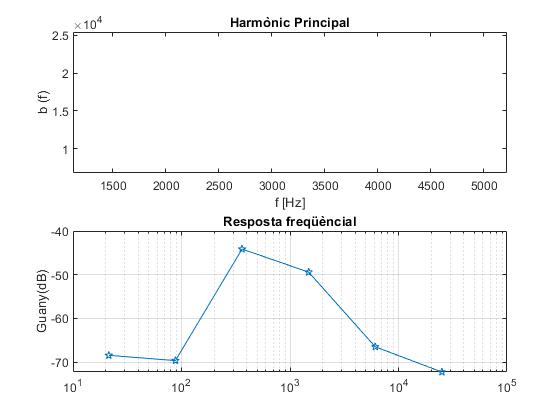

semilogx(freq, gain, '-p');
title('Resposta freqüèncial');
ylabel('Guany(dB)');
grid on